# Dati simulazione 

clear; close all; clc

T_sim = 60;

#### conversione

- base del barile: $0\ldotp 1\;m^2$

- 
$$1\;{\mathrm{kg}}_{\;\mathrm{acqua}} =0\ldotp 001\;m^3$$


## Dati da inserire

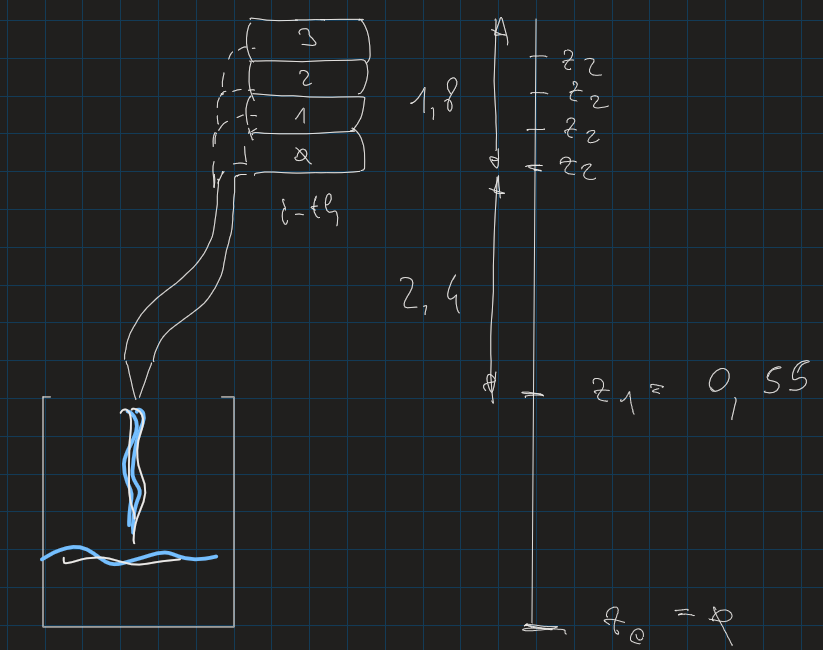

r_barile = 0.1784;            % [m]   raggio della base del barile 

z1 = 0.55;                    % [m]
i_th = 0;                     % [adim]  i-esimo serbatoio (in altezza)
z2 = z1+ 2.4 + i_th*(1.8/4)   % [m] 

rho_l = 1000;                 % [kg/m^3]   densità del liquido
g = 9.81;                     % [m/s^2]    acc. di gravità
gamma_l = rho_l * g;          % [N / m^3]  peso specifico del liquido

p_atm = 101325;               % [Pa]
dp_serbatoio = 100;           % [Pa]
p2 = p_atm + dp_serbatoio;    % [Pa] pressione pelo dell'acqua serbatoio
p1 = p_atm;                   % [Pa] pressione uscita dall'ugello

v2 = 0;                       % [m/s^2] velocità pelo dell'acqua serbatoio
% v1 = incognita              % velocità appena uscito dall'ugello


## Viscosità

Le **perdite di carico continue**, attribuibili alla viscosità, sono compendiate dalla nota formula di Darcy-Weisbach: 

[Perdite di carico nelle tubazioni (edutecnica.it)](https://www.edutecnica.it/macchine/carico/carico.htm)

$y_{c\;} =\lambda \;\frac{L}{d}\cdot \left(\frac{v^2 }{2g}\right)$                     se regime laminare   $\lambda =\frac{\;64}{\mathrm{Re}}$             

L: lunghezza del tubo                                                 d: diametro del tubo

v: velocità del fluido                                                    g: accelerazione di gravità


$$\mathrm{Re}=\frac{\;\rho \;v\;d}{\mu \;}$$


v:  velocità del flusso                                                    d: diametro del tubo

$\mu$: viscosità dinamica   $\left\lbrack \mathrm{Pa}\cdot s\right\rbrack \;\left\lbrack N\cdot \frac{s}{m^2 }\right\rbrack \left\lbrack \frac{\;\mathrm{kg}}{m\cdot s}\right\rbrack$          $\rho$: densità

L_tubo 
d_tubo
v_tubo
mu_acqua 
dmu_l
mu_l = mu_acqua + dmu_l

Re = rho_l * v_tubo * d_tubo / mu_l
lambda = 64/Re;
yc = lambda * (L_tubo/d_tubo) * (v_tubo^2 / (2*g))


theta_piccolo = deg2rad(45);           % [rad]
theta_grande  = deg2rad(40);           % [rad]
r_piccolo     = 0.005;                 % [m]                    
r_grande      = 0.01;                  % [m]
h_limite      = 0.01;                  % [m] altezza massiam oltre la quale si apre anche il grande

base_barile = pi * r_barile^2;  % [m^2]
m_to_kg = 0.1 * 1000;       % da altezza liquido nel barile in kg di liquido
kg_to_m = 10 * 0.001;       % da kg in altezza liquido nel barile